# get a section of the sound file

[x, Fs] = audioread('track.mp3');	% load an audio file
x = x(:, 1);                     	% get the first channel
N = length(x);                   	% signal length
to = (0:N-1)/Fs;

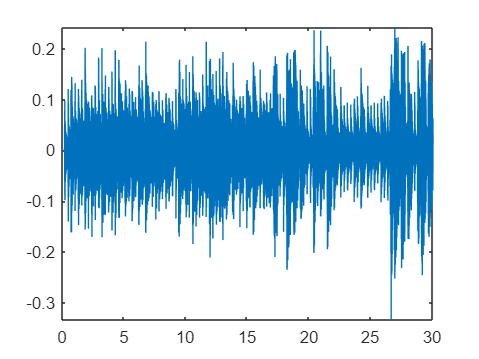

figure(1);
plot(to, x)
xlim([min(to) max(to)]);
ylim([min(x) max(x)]);

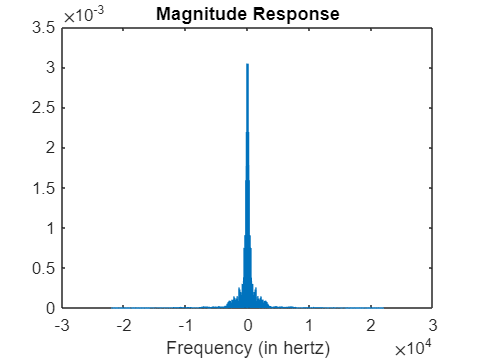

 %%Fourier Transform:
X = fftshift(fft(x));
%%Frequency specifications:
dF = Fs/N;                      % hertz
f = -Fs/2:dF:Fs/2-dF;           % hertz
%%Plot the spectrum:
figure;
plot(f,abs(X)/N);
xlabel('Frequency (in hertz)');
title('Magnitude Response');

index = find(f == 0);
power = sum(abs(X));
power90 = 0.90*power

power90 = 1.3171e+07

sum_ = abs(X(index));
count = 0;

while sum_ < power90
    count = count + 1;
    sum_ = sum_ + abs(X(index+count)) + abs(X(index-count));
end
f(index+count)

ans = 7.6188e+03

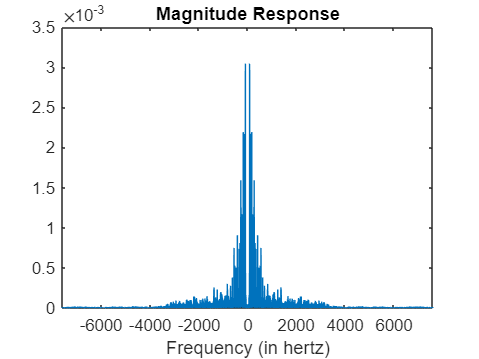


figure;
plot(f,abs(X)/N);
xlabel('Frequency (in hertz)');
title('Magnitude Response');
xlim([-f(index+count) f(index+count)])


sum(X(index-count:index+count))

ans = 1.3681e+04 - 5.9117e-11i